## **Programming workshop: representational similarity analysis (RSA)**

In this programming workshop, we will perform several analyses related to representational similarity analysis.

We will use some data from [Reber et al., PLOS Biology, 2019](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3000290). The data can be downloaded from GitHub [here](https://github.com/rebrowski/abstractRepresentationsInMTL).

Please refer to the paper to read about the details.

If you are very quick with programming everything, please try to recreate all figures from the paper.

You may also want to check out the original paper on representational similarity analysis by [Kriegeskorte et al., Frontiers in Systems Neuroscience, 2008](https://www.frontiersin.org/articles/10.3389/neuro.06.004.2008/full).

## Goal of this programming workshop

Please write some Matlab code to see whether the activity of population of neurons in the human medial temporal lobe contain information about the semantic content of visual stimuli.

If this is the case, this will give us important insights into the functional specialization of these regions.

## Section 1: loading the data

Write some code to load the data. Have a look at the data structure and extract the relevant information.

% room for your code

## Section 2: estimating the similarity of visual stimuli based on their neural firing rates

Write some code to estimate the neural similarity using Pearson correlations.

Create some nice figures to understand the output.

% room for your code

## Section 3: characterizing the representational similarities

Write some code for further understand the population codes.

Before doing this, ask yourself: what could be interesting types of information to extract?

% room for your code

## Section 4: decoding stimulus categories

Write some code to decode category identity using the neural population activity.

Use a kNN classier and/or an SVM classifier. Think about the advantages and distadvantages of these types of classifiers.

% room for your code

## Section 5: helper code

In case you have trouble writing your own code, feel free to get some inspiration from the code below.

You can also check out the code provided in the [paper itself](https://github.com/rebrowski/abstractRepresentationsInMTL).

### Setting up the environment

% add path to be able to load the data
reberPath = 'G:\My Drive\GitCode\ThomasReber\abstractRepresentationsInMTL\'; % adjust according to your setup
addpath(reberPath);

### Obtaining the data

% load the data
data = load(strcat(reberPath, 'zvals.mat'));

% get relevant information from the data
zvals = data.zvals;
categories = data.cat_lookup;
stimuli = data.stim_lookup;
regions = data.cluster_lookup.regionname;

% unique brain regions
uniqueRegions = unique(regions);

% inspect the matrix of z-values
[nRows, nColumns] = size(zvals);
fprintf('The zvals matrix has the size: rows = %d x columns = %d\n', nRows, nColumns);

The zvals matrix has the size: rows = 5033 x columns = 100


**Please answer the following questions:**

- What kind of stimuli and stimulus categories are contained in the data?

- Which regions did the study investigate? What are the general functions of these regions?

- What do the z-values mean?

- How do you compute the z-values?

- How many neurons and how many stimuli are we going to investigate.

## Neural similarity of exemplars and categories

Let's test whether the neural populations contain information about the types of stimuli that were shown to the participants.

To this end, separately for each brain region, we will thus compute the similarity of the neural responses between all stimuli. If some information about stimulus category is contained in the population activity, then different exemplars of the same category should exhibit higher similarity values than exemplars from different categories.

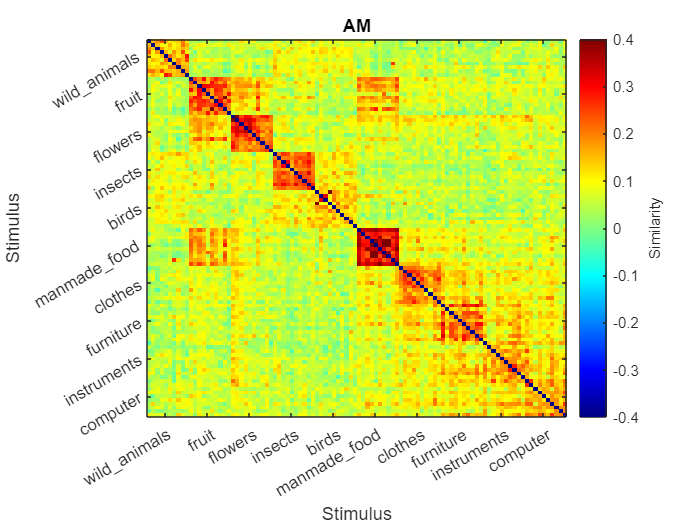

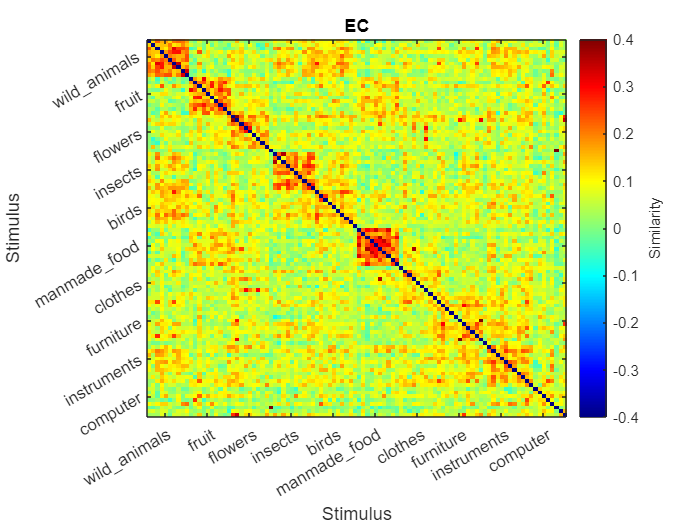

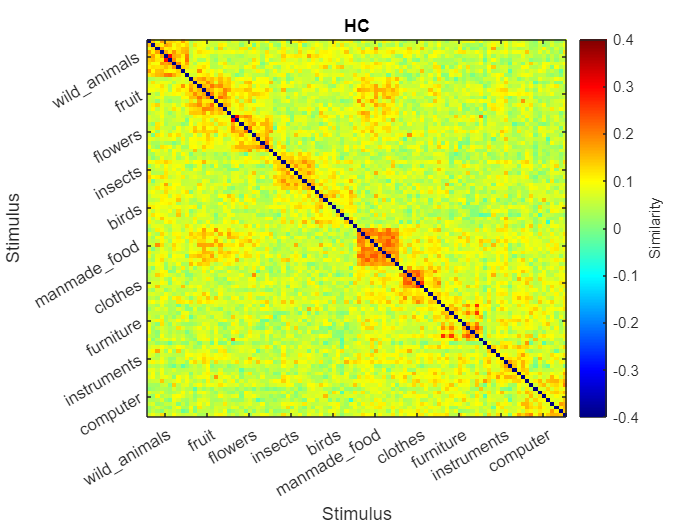

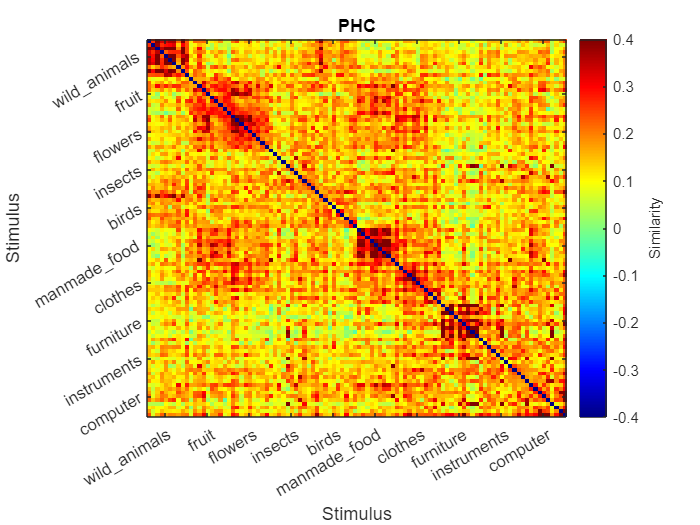

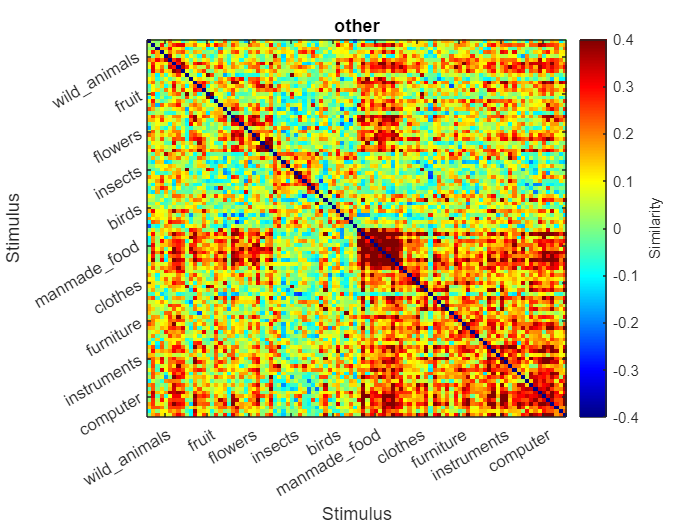

% loop through brain regions
for iRegion = 1:size(uniqueRegions, 1)

    % get the data from this brain region
    bRegion = strcmp(regions, uniqueRegions{iRegion});
    thisZvals = zvals(bRegion, :);

    % compute neural similarity between all stimuli
    R = corr(thisZvals);

    % set self correlations to nan
    bSelf = eye(size(R)) == 1;
    R(bSelf) = nan;

    % create figure
    figure;
    imagesc(R);
    clim([-0.4, 0.4]); % clim([0.6, 1.1]);
    colormap jet;
    cb = colorbar;
    ylabel(cb, 'Similarity');
    xticks(5:10:size(R, 2));
    xticklabels(strrep(categories(5:10:size(R, 2)), '_', '\_'));
    xtickangle(30);
    xlabel('Stimulus');
    yticks(5:10:size(R, 1));
    ytickangle(30);
    yticklabels(strrep(categories(5:10:size(R, 1)), '_', '\_'));
    ylabel('Stimulus');
    title(uniqueRegions{iRegion});
end

## Neural dissimilarity of exemplars and categories

In RSA studies, the metric 1-R (i.e., 1 minus similarity) is often used to display the results.

This procedure was also used in Reber et al., 2019. Let's use this procedure here and reproduce Fig. 3, A-D, in Reber et al., 2019.

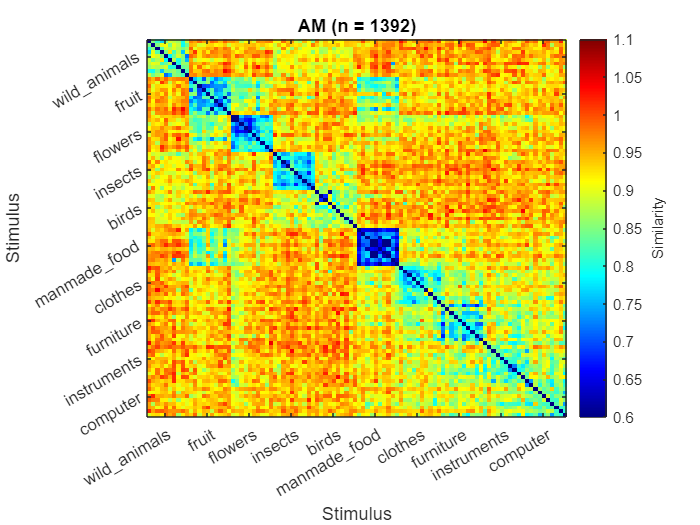

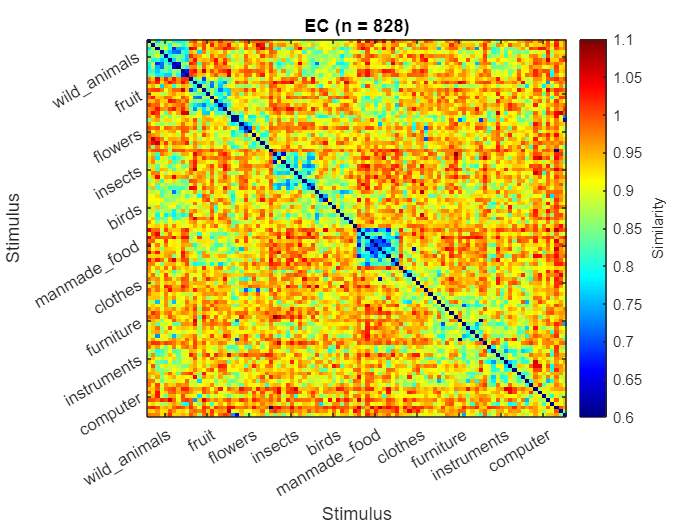

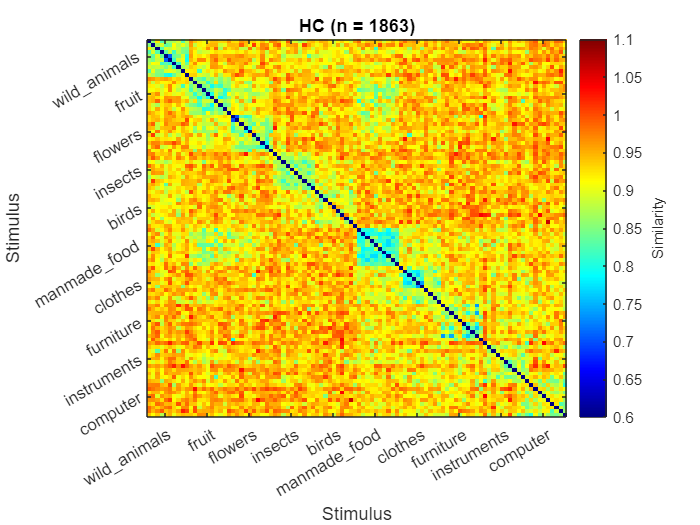

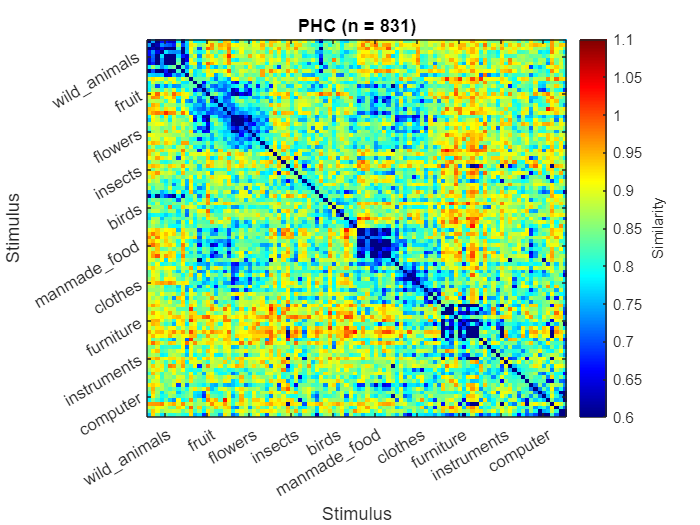

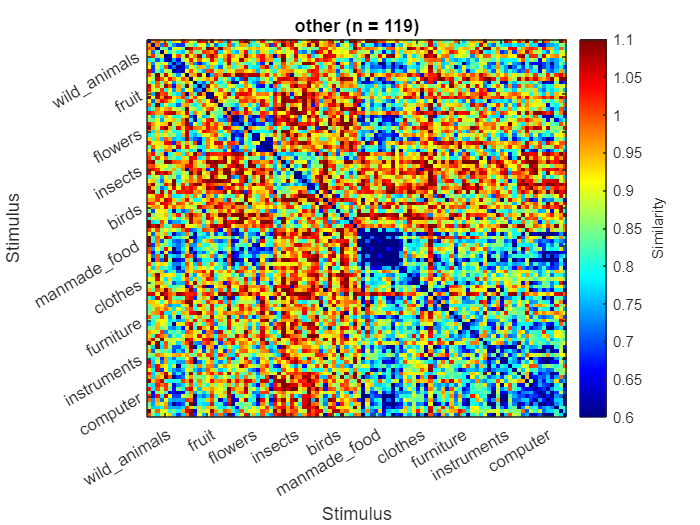

% loop through brain regions
for iRegion = 1:size(uniqueRegions, 1)

    bRegion = strcmp(regions, uniqueRegions{iRegion});
    thisZvals = zvals(bRegion, :);

    % compute dissimilarity
    R = corr(thisZvals);
    dissim = 1 - R;

    % create figure
    figure;
    imagesc(dissim);
    clim([0.6, 1.1]); % following Reber et al., 2019
    colormap jet;
    cb = colorbar;
    ylabel(cb, 'Similarity');
    xticks(5:10:size(R, 2));
    xticklabels(strrep(categories(5:10:size(R, 2)), '_', '\_'));
    xtickangle(30);
    xlabel('Stimulus');
    yticks(5:10:size(R, 1));
    ytickangle(30);
    yticklabels(strrep(categories(5:10:size(R, 1)), '_', '\_'));
    ylabel('Stimulus');
    title(sprintf('%s (n = %d)', uniqueRegions{iRegion}, size(thisZvals, 1)));
end

**Please answer the following question:**

- Which region contains the most distinct neural representations?

- In which region are the neural representations most similar across categories and exemplars?

## Decoding category identity

An important question in neuroscience is whether neural activity can be used to predict the subject's current mental state.

Using more or less sophisticated classification algorithms, this has indeed become possible.

For example, in the context of brain-machine interfaces (BMIs), decoding neural activity in the human motor cortex allows to decipher what kind of limb movements a participant (including patients with tetraplegia) wants to perform. Here is an example paper: [https://www.thelancet.com/journals/lancet/article/PIIS0140-6736(12)61816-9/abstract](https://www.thelancet.com/journals/lancet/article/PIIS0140-6736(12)61816-9/abstract)

Let's write some code to decode category identity using the z-scored firing rates provided by Reber et al., 2019.

% decide what kind of classifier you want to use
classifierType = "knn"; % "knn" or "svm"

% settings for the knn classifier: number of neighbors
k = 1;

% convert data to proper orientation for ML in MATLAB (features in rows)
X = transpose(zvals);
Y = categories;

% set up cross-validation
cv = cvpartition(Y, 'KFold', 5);

% preallocate array to save accuracy for each fold
accuracy = zeros(cv.NumTestSets, 1);

% loop through folds
for iFold = 1:cv.NumTestSets
    
    % split into training and test sets
    trainIdx = cv.training(iFold);
    testIdx = cv.test(iFold);
    
    % create a kNN model
    if classifierType == "knn"
        mdl = fitcknn(X(trainIdx, :), Y(trainIdx), 'NumNeighbors', k);
    elseif classifierType == "svm"
        mdl = fitcecoc(X(trainIdx,:), Y(trainIdx));
    end

    % predict the labels of the test set
    predictions = predict(mdl, X(testIdx, :));
    
    % Calculate accuracy
    accuracy(iFold) = sum(strcmp(predictions, Y(testIdx))) / numel(Y(testIdx));
end

Let's have a look at the classifier accuracy.

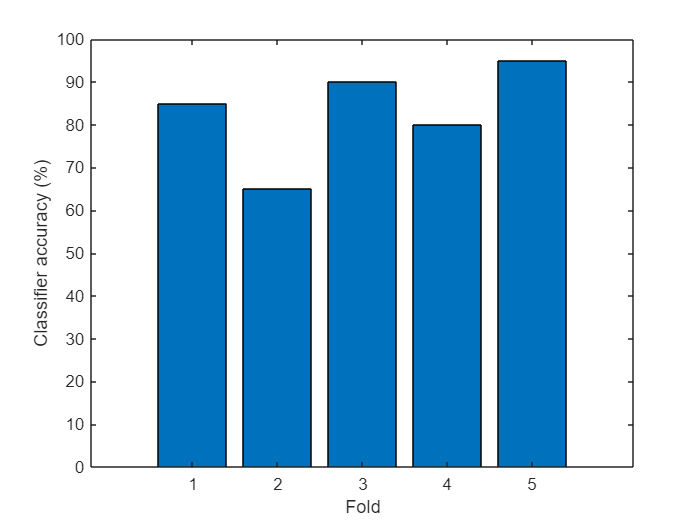

% create figure to show the accuracy per fold
figure;
bar(accuracy * 100);
xlabel('Fold');
ylabel('Classifier accuracy (%)');

% average accuracy across folds
meanAccuracy = mean(accuracy);

% report
fprintf('Average accuracy: %.2f%%\n', meanAccuracy * 100);

Average accuracy: 83.00%


**Please answer some questions:**

What does this accuracy value mean?

What is the chance level?

Is it better to use a kNN classifier or an SVM classifier?

What are the advantages and disadvantages of an SVM classifier as compared to a kNN classifier?

Why do you need to partition the data into training and testing sets?

What is cross-validation?